# Do LDE

## 0. All pars needed. Using one canonical set here

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Figures/Demo082721/'];
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Figures/Demo082121/'];
addpath(DataFolder)

First read old network structure, get our desired Numbers of presyn neurons

% load('NtWk_Archit.mat')
% E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
% [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
% E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
% I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
% [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
% I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);
% 
% N_EE = full(mean(sum(C_EE(E_Ind,:),2))); N_EI = full(mean(sum(C_EI(E_Ind,:),2))*0.75); %*0.75
% N_IE = full(mean(sum(C_IE(I_Ind,:),2))); N_II = full(mean(sum(C_II(I_Ind,:),2))*0.75); %*0.75 Plan A:Original

Then use the new function to generate new network stucture


%% If now, we start computation below...
% Frst setup network
N_HC = 3;
% Number of E and I neurons
n_S_HC = 45; n_C_HC = 30; n_I_HC = 31; % per side of HC
N_S = n_S_HC^2 * N_HC^2; % neuron numbers In all
N_C = n_C_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
N_E = N_S+N_C; CplxR = N_C/N_E;
% Grid sizes of E and I neurons;
Size_HC = 0.500; % in mm;
Size_S = Size_HC/n_S_HC; Size_C = Size_HC/n_C_HC; Size_I = Size_HC/n_I_HC;
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6;

% spatial indexes of E and I neurons
[NnS.X,NnS.Y] = V1Field_Generation(N_HC,1:N_S,'e',n_S_HC,n_I_HC);
[NnC.X,NnC.Y] = V1Field_Generation(N_HC,1:N_C,'e',n_C_HC,n_I_HC);
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');
%NnE.X = [NnS.X,NnC.X]; NnE.Y = [NnS.Y,NnC.Y];

We are fixing boundary effect by connecting neurons to similar ODs

% Extended spatial indexes of E and I neurons (1HC each side)
Nex_S = n_S_HC^2 * (N_HC+2)^2; % neuron numbers In all
Nex_C = n_C_HC^2 * (N_HC+2)^2; 
Nex_I = n_I_HC^2 * (N_HC+2)^2;
[NnSex.X,NnSex.Y] = V1Field_Generation(N_HC+2,1:Nex_S,'e',n_S_HC,n_I_HC);
[NnCex.X,NnCex.Y] = V1Field_Generation(N_HC+2,1:Nex_C,'e',n_C_HC,n_I_HC);
[NnIex.X,NnIex.Y] = V1Field_Generation(N_HC+2,1:Nex_I,'i');

Now select complx cells

N_EE = 193; N_EI = 85; %*0.75
N_IE = 844; N_II = 84; %*0.75 Plan A:Original

CplxNEIncr = 253/N_EE; % Was 250 for 071021 simulation
EcplxInd = ismember(1:N_E, N_S+1:N_E); 

N_SS = N_EE * (1-CplxR);            N_SC = N_EE * (CplxR); 
N_CS = N_EE * (1-CplxR)*CplxNEIncr; N_CC = N_EE * (CplxR)*CplxNEIncr;
N_SI = N_EI;                        N_CI = N_EI; 
N_IS = N_IE * (1-CplxR);            N_IC = N_IE * (CplxR); 

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.530; 
rI_amb = 0.435; % was 0.5 for for 071021 simulation

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.8;  % was 1.6 for for 071021 simulation
S_II = 0.120; S_IE = S_II*0.153 * 1.6/1.8;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
N_Slgn = 4.75; N_Clgn = 1.25; N_Ilgn = 4.5;

lambda_E = 0.02*[N_Slgn*ones(N_S,1);N_Clgn*ones(N_C,1)]; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.02*N_Ilgn; 

## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_S = zeros(size(NnS.X),'single');
OD_SMap = zeros(n_S_HC*N_HC,'single');
for NeuInd = 1:length(NnS.X)
OD_S(NeuInd) = OrientDom(ODNum,NnS.X(NeuInd),NnS.Y(NeuInd),n_S_HC);
OD_SMap(NnS.Y(NeuInd),NnS.X(NeuInd)) = OD_S(NeuInd);
end

OD_C = zeros(size(NnC.X),'single');
OD_CMap = zeros(n_C_HC*N_HC,'single');
for NeuInd = 1:length(NnC.X)
OD_C(NeuInd) = OrientDom(ODNum,NnC.X(NeuInd),NnC.Y(NeuInd),n_C_HC);
OD_CMap(NnC.Y(NeuInd),NnC.X(NeuInd)) = OD_C(NeuInd);
end
OD_E = [OD_S, OD_C];

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

StimulusFac = 1;
LGNFreq = 4; % 2 4 10Hz
tMod = 1e3/LGNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = single(tMod*rand(N_E,1));
PhaseFRS = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Slgn/1e3 * StimulusFac; % 4 to 5
%PhaseFRC = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Clgn/1e3 * StimulusFac;
PhaseFRC = 45*ones(1,8) *N_Clgn/1e3 * StimulusFac;
lambda_EOn_drive  = [PhaseFRS(OD_S),PhaseFRC(OD_C)]'; % Should do another for Cplx cells
lambda_EOff_drive = [PhaseFRS(OD_S+ODNum),PhaseFRC(OD_C+ODNum)]';
% T partition
T = 10000; dt = 0.1; TPar = 10;

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lambda_E_drive_Pre = 45 *N_Slgn/1e3 * StimulusFac;
lambda_I_drive_Pre = 45 *N_Ilgn/1e3 * StimulusFac;

L6E_Drive = [50 35 20 35]*50/1e3 * StimulusFac;
rE_L6_Drive = L6E_Drive(OD_E)';
rI_L6_Drive = 3*L6E_Drive(OD_I)';

## 1. Details of NW before gluing everying up

Comparisons of MF+V before LDE

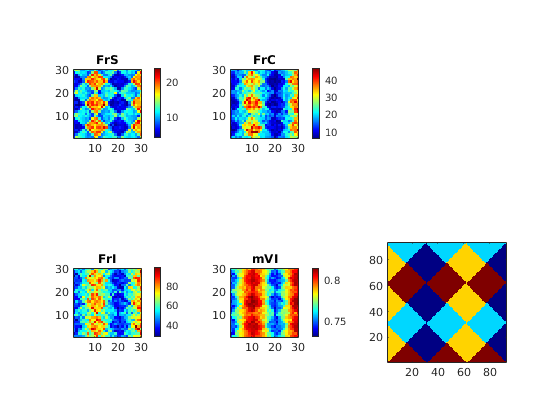

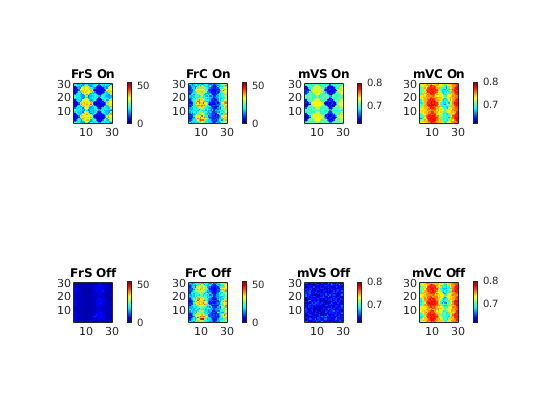

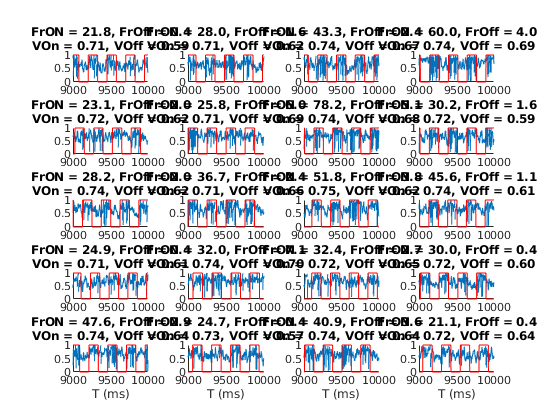

load('AllMFPixPara.mat')

load('MFpVPix_New.mat')
PixNum = 900;
FrMFpV = zeros(5,PixNum);
mVMFpV = zeros(5,PixNum);
for PixInd = 1:PixNum
    FrMFpV(:,PixInd) = mean(f_EnIOut{PixInd}(:,end-25:end),2);
    mVMFpV(:,PixInd) = mean(meanVs{PixInd}(:,end-25:end),2);
end
FrSMFV = ((FrMFpV(1,:) + FrMFpV(3,:))/2)';
FrCMFV = ((FrMFpV(2,:) + FrMFpV(4,:))/2)';
FrIMFV = (FrMFpV(5,:))';
%mVSMFV = ((mVMFpV(1,:) + mVMFpV(3,:))/2)';
mVCMFV = ((mVMFpV(2,:) + mVMFpV(4,:))/2)';
mVIMFV = (mVMFpV(5,:))';

% Connectivity within Pixels 
% C_PQ_Pixel: Average number of presyn neurons from pixel j to i
N_PreSynPixIn = ...
    [mean(diag(C_SS_Pixel_Us)),mean(diag(C_CS_Pixel_Us)),mean(diag(C_IS_Pixel_Us));
     mean(diag(C_SC_Pixel_Us)),mean(diag(C_CC_Pixel_Us)),mean(diag(C_IC_Pixel_Us));
     mean(diag(C_SI_Pixel_Us)),mean(diag(C_CI_Pixel_Us)),mean(diag(C_II_Pixel_Us))];
N_PreSynPixInStd = ...
    [std(diag(C_SS_Pixel_Us)),std(diag(C_CS_Pixel_Us)),std(diag(C_IS_Pixel_Us));
     std(diag(C_SC_Pixel_Us)),std(diag(C_CC_Pixel_Us)),std(diag(C_IC_Pixel_Us));
     std(diag(C_SI_Pixel_Us)),std(diag(C_CI_Pixel_Us)),std(diag(C_II_Pixel_Us))];

% From Outside the Pixels
C_SSO = sum(C_SS_Pixel_Us-diag(diag(C_SS_Pixel_Us)),2);
C_CSO = sum(C_CS_Pixel_Us-diag(diag(C_CS_Pixel_Us)),2);
C_ISO = sum(C_IS_Pixel_Us-diag(diag(C_IS_Pixel_Us)),2);
C_SCO = sum(C_SC_Pixel_Us-diag(diag(C_SC_Pixel_Us)),2);
C_CCO = sum(C_CC_Pixel_Us-diag(diag(C_CC_Pixel_Us)),2);
C_ICO = sum(C_IC_Pixel_Us-diag(diag(C_IC_Pixel_Us)),2);
C_SIO = sum(C_SI_Pixel_Us-diag(diag(C_SI_Pixel_Us)),2);
C_CIO = sum(C_CI_Pixel_Us-diag(diag(C_CI_Pixel_Us)),2);
C_IIO = sum(C_II_Pixel_Us-diag(diag(C_II_Pixel_Us)),2);
N_PreSynPixOut = ...
    [mean(C_SSO),mean(C_CSO),mean(C_ISO);
     mean(C_SCO),mean(C_CCO),mean(C_ICO);
     mean(C_SIO),mean(C_CIO),mean(C_IIO)];
N_PreSynPixOutStd = ...
    [std(C_SSO),std(C_CSO),std(C_ISO);
     std(C_SCO),std(C_CCO),std(C_ICO);
     std(C_SIO),std(C_CIO),std(C_IIO)];

% 3 ODs
OPTPix = lambda_SOn_Pixel>0.42;
OBLPix = lambda_SOn_Pixel>0.30 & lambda_SOn_Pixel<0.33;
ORTPix = lambda_SOn_Pixel<0.22;
% Compute averaged FrE
NSPix = N_S/PixNum; NCPix = N_C/PixNum;
FrEPixNW = (FrSPixVec*NSPix + FrCPixVec*NCPix)/(NSPix+NCPix);
FrEPixMF = (FrSMFV*NSPix + FrCMFV*NCPix)/(NSPix+NCPix);

Load LDE computations and do Fr distributions

fLDE_OPT = load('MFpV_LDE_3.mat','f_EnIOut'); fLDE_OPT = fLDE_OPT.f_EnIOut;
fLDE_OBL = load('MFpV_LDE_2.mat','f_EnIOut'); fLDE_OBL = fLDE_OBL.f_EnIOut;
fLDE_ORT = load('MFpV_LDE_1.mat','f_EnIOut'); fLDE_ORT = fLDE_ORT.f_EnIOut;
FrLDE_opt = zeros(5,length(fLDE_OPT));
FrLDE_obl = zeros(5,length(fLDE_OPT));
FrLDE_ort = zeros(5,length(fLDE_OPT));
for LDEInd = 1:length(fLDE_OPT)
    FrLDE_opt(:,LDEInd) = mean(fLDE_OPT{LDEInd}(:,end-25:end),2);
    FrLDE_obl(:,LDEInd) = mean(fLDE_OBL{LDEInd}(:,end-25:end),2);
    FrLDE_ort(:,LDEInd) = mean(fLDE_ORT{LDEInd}(:,end-25:end),2);
end
FrLDE_optE = ((FrLDE_opt(1,:)+FrLDE_opt(3,:))/2 * NSPix + ...
              (FrLDE_opt(2,:)+FrLDE_opt(4,:))/2 * NCPix)/(NSPix+NCPix);
FrLDE_oblE = ((FrLDE_obl(1,:)+FrLDE_obl(3,:))/2 * NSPix + ...
              (FrLDE_obl(2,:)+FrLDE_obl(4,:))/2 * NCPix)/(NSPix+NCPix);
FrLDE_ortE = ((FrLDE_ort(1,:)+FrLDE_ort(3,:))/2 * NSPix + ...
              (FrLDE_ort(2,:)+FrLDE_ort(4,:))/2 * NCPix)/(NSPix+NCPix);
% Do hist2
XOPT = linspace(12,51,30); YOPT = linspace(45,143,30);
NW_OPT = histcounts2(FrEPixNW(OPTPix),FrIPixVec(OPTPix),XOPT,YOPT);
LDE_OPT = histcounts2(FrLDE_optE,FrLDE_opt(5,:),XOPT,YOPT);
XOBL = linspace(5,32,30); YOBL = linspace(27,114,30);
NW_OBL = histcounts2(FrEPixNW(OBLPix),FrIPixVec(OBLPix),XOBL,YOBL);
LDE_OBL = histcounts2(FrLDE_oblE,FrLDE_obl(5,:),XOBL,YOBL);
XORT = linspace(2,20,30); YORT = linspace(14,92,30);
NW_ORT = histcounts2(FrEPixNW(ORTPix),FrIPixVec(ORTPix),XORT,YORT);
LDE_ORT = histcounts2(FrLDE_ortE,FrLDE_ort(5,:),XORT,YORT);


Figures for comparison

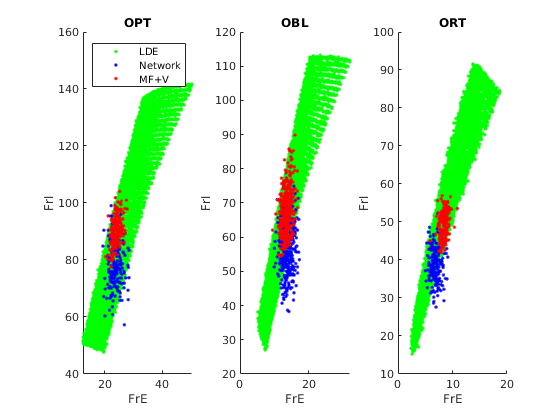

figure('Name','FrRanges')
subplot 131
hold on
scatter(FrLDE_optE,FrLDE_opt(5,:),'g.','DisplayName','LDE')
scatter(FrEPixNW(OPTPix),FrIPixVec(OPTPix),'b.','DisplayName','Network')
scatter(FrEPixMF(OPTPix),FrIMFV(OPTPix),'r.','DisplayName','MF+V')
legend
xlabel('FrE');ylabel('FrI');
title('OPT')

subplot 132
hold on
scatter(FrLDE_oblE,FrLDE_obl(5,:),'g.')
scatter(FrEPixNW(OBLPix),FrIPixVec(OBLPix),'b.')
scatter(FrEPixMF(OBLPix),FrIMFV(OBLPix),'r.')
xlabel('FrE');ylabel('FrI');
title('OBL')

subplot 133
hold on
scatter(FrLDE_ortE,FrLDE_ort(5,:),'g.')
scatter(FrEPixNW(ORTPix),FrIPixVec(ORTPix),'b.')
scatter(FrEPixMF(ORTPix),FrIMFV(ORTPix),'r.')
xlabel('FrE');ylabel('FrI');
title('ORT')

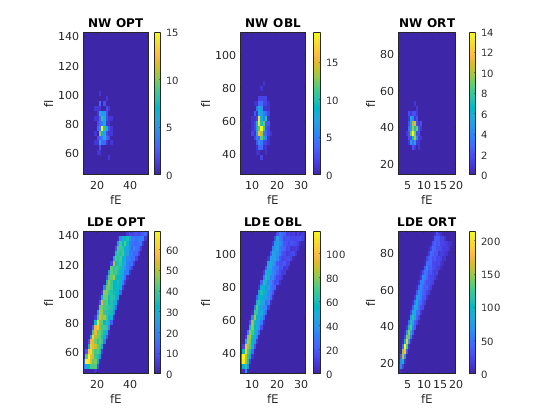


figure("Name",'FrDistb')
subplot 231
imagesc((XOPT(1:end-1)+XOPT(2:end))/2,(YOPT(1:end-1)+YOPT(2:end))/2,NW_OPT')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW OPT')
subplot 234
imagesc((XOPT(1:end-1)+XOPT(2:end))/2, (YOPT(1:end-1)+YOPT(2:end))/2, LDE_OPT')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE OPT')
subplot 232
imagesc((XOBL(1:end-1)+XOBL(2:end))/2, (YOBL(1:end-1)+YOBL(2:end))/2, NW_OBL')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW OBL')
subplot 235
imagesc((XOBL(1:end-1)+XOBL(2:end))/2, (YOBL(1:end-1)+YOBL(2:end))/2,LDE_OBL')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE OBL')
subplot 233
imagesc((XORT(1:end-1)+XORT(2:end))/2, (YORT(1:end-1)+YORT(2:end))/2,NW_ORT')
set(gca,'YDir','normal');colorbar
ylabel('fI'); xlabel('fE'); title('NW ORT')
subplot 236
imagesc((XORT(1:end-1)+XORT(2:end))/2, (YORT(1:end-1)+YORT(2:end))/2,LDE_ORT')
set(gca,'YDir','normal'); colorbar
ylabel('fI'); xlabel('fE'); title('LDE ORT')

## 2. Set up LDE firing rate functions

from HPC LDE computed results

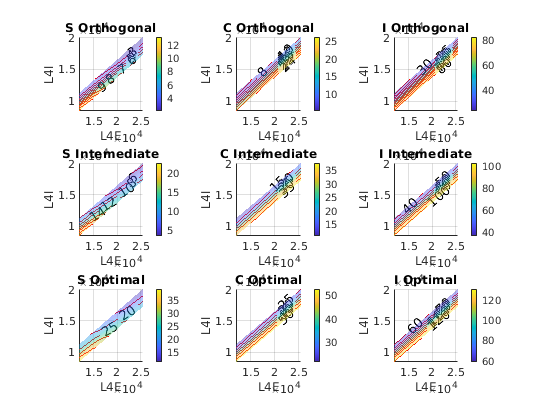

ans =    13.1762   13.1348   13.0899   13.0405   13.0013   12.9571   12.9138   12.8771   12.8380   12.7958   12.7510   12.7150   12.6784   12.6381   12.5991   12.5584   12.5201   12.4803   12.4426   12.4022   12.3649   12.3257   12.2843   12.2492   12.2095   12.1702   12.1287   12.0896   12.0548   12.0177   11.9812   11.9011   11.8221   11.7413   11.6645   11.5862   11.5102   11.4339   11.3570   11.2839   11.2074   11.1352   11.0619   10.9912   10.9207   10.8474   10.7777   10.7064   10.6384   10.5693
   13.0156   12.9746   12.9303   12.8823   12.8447   12.8010   12.7585   12.7211   12.6827   12.6402   12.5966   12.5604   12.5243   12.4853   12.4473   12.4071   12.3691   12.3293   12.2923   12.2525   12.2154   12.1761   12.1346   12.0998   12.0611   12.0226   11.9824   11.9434   11.9088   11.8720   11.8353   11.7572   11.6785   11.5986   11.5234   11.4468   11.3723   11.2966   11.2210   11.1495   11.0732   11.0016   10.9291   10.8592   10.7902   10.7173   10.6484   10.5769   10.5093   

ans =    20.2776   20.3098   20.3420   20.3729   20.4086   20.4422   20.4725   20.5072   20.5406   20.5757   20.6114   20.6464   20.6823   20.7121   20.7446   20.7748   20.8080   20.8422   20.8711   20.9032   20.9368   20.9692   20.9991   21.0332   21.0650   21.0980   21.1302   21.1616   21.1947   21.2274   21.2594   21.3249   21.3913   21.4555   21.5208   21.5870   21.6559   21.7196   21.7829   21.8444   21.9062   21.9671   22.0308   22.0975   22.1615   22.2209   22.2815   22.3401   22.3991   22.4611
   20.0412   20.0732   20.1055   20.1362   20.1718   20.2058   20.2369   20.2709   20.3038   20.3378   20.3738   20.4082   20.4437   20.4735   20.5056   20.5363   20.5692   20.6030   20.6326   20.6646   20.6985   20.7304   20.7604   20.7940   20.8253   20.8587   20.8909   20.9222   20.9550   20.9870   21.0187   21.0843   21.1499   21.2146   21.2806   21.3468   21.4156   21.4789   21.5434   21.6053   21.6675   21.7285   21.7927   21.8595   21.9232   21.9830   22.0442   22.1021   22.1611   

ans =    75.9908   76.0333   76.0758   76.1198   76.1610   76.2020   76.2441   76.2869   76.3301   76.3729   76.4085   76.4497   76.4912   76.5359   76.5693   76.6130   76.6560   76.6954   76.7355   76.7763   76.8129   76.8496   76.8886   76.9276   76.9637   77.0014   77.0376   77.0740   77.1137   77.1502   77.1832   77.2612   77.3399   77.4165   77.4920   77.5683   77.6475   77.7231   77.7951   77.8698   77.9395   78.0101   78.0848   78.1572   78.2286   78.3049   78.3769   78.4479   78.5191   78.5932
   75.2483   75.2911   75.3333   75.3781   75.4199   75.4616   75.5050   75.5480   75.5920   75.6355   75.6718   75.7139   75.7558   75.8003   75.8349   75.8774   75.9202   75.9603   75.9995   76.0400   76.0777   76.1154   76.1539   76.1933   76.2298   76.2683   76.3057   76.3427   76.3819   76.4192   76.4530   76.5312   76.6111   76.6887   76.7650   76.8413   76.9223   76.9991   77.0726   77.1488   77.2190   77.2910   77.3668   77.4394   77.5122   77.5885   77.6612   77.7332   77.8053   

ans =    22.5026   22.4097   22.3142   22.2246   22.1343   22.0398   21.9476   21.8564   21.7641   21.6728   21.5829   21.4946   21.4046   21.3180   21.2326   21.1460   21.0605   20.9736   20.8898   20.8058   20.7233   20.6392   20.5562   20.4723   20.3919   20.3114   20.2312   20.1552   20.0768   19.9987   19.9226   19.7536   19.5863   19.4212   19.2564   19.0905   18.9315   18.7730   18.6165   18.4587   18.3035   18.1547   18.0025   17.8541   17.7076   17.5626   17.4196   17.2779   17.1362   16.9979
   22.2197   22.1284   22.0338   21.9450   21.8561   21.7633   21.6725   21.5825   21.4918   21.4019   21.3135   21.2269   21.1381   21.0526   20.9688   20.8837   20.7999   20.7143   20.6321   20.5494   20.4686   20.3859   20.3042   20.2223   20.1437   20.0649   19.9864   19.9116   19.8349   19.7583   19.6837   19.5175   19.3525   19.1901   19.0285   18.8653   18.7085   18.5528   18.3994   18.2447   18.0921   17.9455   17.7961   17.6509   17.5068   17.3641   17.2235   17.0844   16.9455   

ans =    34.3958   34.4155   34.4339   34.4515   34.4768   34.4974   34.5146   34.5318   34.5472   34.5647   34.5844   34.6056   34.6237   34.6423   34.6619   34.6806   34.7002   34.7175   34.7352   34.7539   34.7742   34.7959   34.8127   34.8303   34.8479   34.8679   34.8839   34.9020   34.9206   34.9383   34.9565   34.9925   35.0261   35.0601   35.0958   35.1329   35.1694   35.2047   35.2393   35.2767   35.3080   35.3435   35.3764   35.4104   35.4446   35.4775   35.5146   35.5507   35.5825   35.6158
   34.0649   34.0861   34.1053   34.1230   34.1479   34.1687   34.1860   34.2031   34.2192   34.2370   34.2556   34.2769   34.2947   34.3144   34.3326   34.3518   34.3716   34.3890   34.4069   34.4252   34.4453   34.4670   34.4846   34.5020   34.5198   34.5394   34.5561   34.5741   34.5929   34.6105   34.6293   34.6658   34.7001   34.7347   34.7719   34.8090   34.8452   34.8809   34.9159   34.9537   34.9854   35.0215   35.0548   35.0891   35.1223   35.1548   35.1918   35.2279   35.2607   

ans =   101.9300  101.9421  101.9549  101.9680  101.9813  101.9960  102.0087  102.0234  102.0343  102.0468  102.0561  102.0655  102.0813  102.0952  102.1079  102.1208  102.1334  102.1461  102.1581  102.1684  102.1792  102.1868  102.1973  102.2060  102.2159  102.2250  102.2348  102.2481  102.2586  102.2683  102.2757  102.2978  102.3233  102.3436  102.3674  102.3890  102.4072  102.4290  102.4497  102.4690  102.4888  102.5085  102.5242  102.5402  102.5597  102.5808  102.5986  102.6131  102.6258  102.6411
  101.1060  101.1179  101.1315  101.1452  101.1589  101.1740  101.1871  101.2028  101.2134  101.2255  101.2350  101.2455  101.2615  101.2753  101.2881  101.3013  101.3144  101.3275  101.3394  101.3501  101.3616  101.3690  101.3798  101.3889  101.3993  101.4088  101.4190  101.4318  101.4428  101.4524  101.4602  101.4819  101.5075  101.5285  101.5530  101.5752  101.5949  101.6177  101.6395  101.6594  101.6796  101.6997  101.7160  101.7327  101.7533  101.7745  101.7927  101.8079  101.8210  1

ans =    39.3696   39.2511   39.1314   39.0078   38.8852   38.7678   38.6475   38.5304   38.4125   38.2971   38.1827   38.0679   37.9543   37.8418   37.7295   37.6198   37.5091   37.3981   37.2897   37.1826   37.0752   36.9672   36.8623   36.7584   36.6541   36.5513   36.4497   36.3489   36.2473   36.1487   36.0494   35.8346   35.6236   35.4125   35.2039   34.9971   34.7925   34.5914   34.3903   34.1912   33.9937   33.7992   33.6061   33.4146   33.2253   33.0377   32.8540   32.6706   32.4874   32.3110
   39.0376   38.9203   38.8020   38.6800   38.5596   38.4440   38.3253   38.2103   38.0945   37.9809   37.8688   37.7563   37.6446   37.5342   37.4238   37.3164   37.2077   37.0987   36.9924   36.8876   36.7826   36.6767   36.5735   36.4713   36.3687   36.2675   36.1677   36.0688   35.9692   35.8725   35.7751   35.5633   35.3549   35.1467   34.9410   34.7370   34.5355   34.3372   34.1393   33.9429   33.7485   33.5566   33.3670   33.1784   32.9917   32.8071   32.6262   32.4458   32.2660   

ans =    52.5539   52.5536   52.5577   52.5641   52.5685   52.5716   52.5743   52.5776   52.5794   52.5800   52.5835   52.5849   52.5892   52.5919   52.5930   52.5970   52.5982   52.6001   52.6008   52.5992   52.6028   52.6105   52.6154   52.6219   52.6281   52.6328   52.6397   52.6462   52.6541   52.6599   52.6662   52.6698   52.6752   52.6799   52.6828   52.6880   52.6942   52.6959   52.6993   52.7019   52.7045   52.7095   52.7157   52.7179   52.7206   52.7236   52.7278   52.7292   52.7349   52.7377
   52.1477   52.1483   52.1519   52.1594   52.1638   52.1669   52.1707   52.1741   52.1771   52.1795   52.1831   52.1845   52.1887   52.1914   52.1934   52.1977   52.1998   52.2015   52.2023   52.2013   52.2057   52.2142   52.2200   52.2273   52.2341   52.2401   52.2471   52.2537   52.2613   52.2682   52.2743   52.2782   52.2850   52.2887   52.2923   52.2983   52.3049   52.3068   52.3111   52.3146   52.3174   52.3226   52.3285   52.3317   52.3348   52.3387   52.3427   52.3437   52.3495   

% Determine L4 Input from a range
% Expectation of kick numbers received by 1 neuron in each type
L4SE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4SI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4IE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4II = zeros(N_HC*NPixX*N_HC*NPixY,1);
for PInd = 1:N_HC*NPixX*N_HC*NPixY
L4SE(PInd) = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec)...
            - C_SS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_SC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4SI(PInd) =  C_SI_Pixel_Us(PInd,:)*FrIPixVec - C_SI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
L4CE(PInd) = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec)...
            - C_CS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_CC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4CI(PInd) =  C_CI_Pixel_Us(PInd,:)*FrIPixVec - C_CI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
L4IE(PInd) = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec)...
            - C_IS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_IC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4II(PInd) =  C_II_Pixel_Us(PInd,:)*FrIPixVec - C_II_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
end
% Proportions between the distributions of kicks to SCI cells
% Assumption here: Total kicks received by the same pixel should be
% proportional to SCI
L4Eall = L4SE+L4CE+L4IE; L4Iall = L4SI+L4CI+L4II;
L4SEp = mean(L4SE./L4Eall);L4CEp = mean(L4CE./L4Eall);L4IEp = mean(L4IE./L4Eall);
L4SIp = mean(L4SI./L4Iall);L4CIp = mean(L4CI./L4Iall);L4IIp = mean(L4II./L4Iall);
LineFit = polyfit(L4Eall,L4Iall,1);
YRange = L4Iall - (LineFit(1)*L4Eall+LineFit(2)); % We plan to use 2 times of the range
Bdry = floor(max(abs(YRange))/100)*100;
L4ERange = floor(min(L4Eall)/100)*100:100:ceil(max(L4Eall)/100)*100;
L4IDiffRange = -2*Bdry:50:2*Bdry;

a1 = length(L4ERange); a2 = length(L4IDiffRange);

figure('Name','LDERateFunctions')
CtgrName = {'Orthogonal','Intemediate','Optimal'};
LDEFrVecS = zeros(length(L4ERcrd),3);
LDEFrVecC = zeros(length(L4ERcrd),3);
LDEFrVecI = zeros(length(L4ERcrd),3);
for Ctgr = 1:3
    load(['MFpV_LDE_' num2str(Ctgr) '.mat'])
    L4EPlot = reshape(L4ERcrd,a2,a1);
    L4IPlot = reshape(L4IRcrd,a2,a1);
    FrLDE = zeros(length(f_EnIOut),5);
    for LDEInd = 1:length(f_EnIOut)
        FrLDE(LDEInd,:) = (mean(f_EnIOut{LDEInd}(:,end-25:end),2))';
    end
    % S rates
    subplot(3,3,(Ctgr-1)*3+1)
    LDEFrVecS(:,Ctgr) = ...
    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'S',true);
    
    % C rates
    subplot(3,3,(Ctgr-1)*3+2)
    LDEFrVecC(:,Ctgr) = ...
    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'C',true); 
    
    % I rates
    subplot(3,3,(Ctgr-1)*3+3)
    LDEFrVecI(:,Ctgr) = ...
    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'I',true); 
end

Create a function

L4EfuncX = linspace(min(L4ERcrd),max(L4ERcrd),400); 
L4IfuncY = linspace(min(L4IPlot,[],'all'),max(L4IPlot,[],'all'),300);
[L4EmeshX, L4ImeshY] = meshgrid(L4EfuncX,L4IfuncY);
% 2D function now, depending on input of total E and I kick numbers
LDEFrfunc.S.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.S.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.S.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,3),L4EmeshX, L4ImeshY);
LDEFrfunc.C.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.C.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.C.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,3),L4EmeshX, L4ImeshY);
LDEFrfunc.I.ORT = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,1),L4EmeshX, L4ImeshY);
LDEFrfunc.I.OBL = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,2),L4EmeshX, L4ImeshY);
LDEFrfunc.I.OPT = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,3),L4EmeshX, L4ImeshY);

## 3. Now Start Iteration

First, get an averaged Fr integration kernal

Write a function to smooth the integration kernel